In this document we will explore the concept of a "valid design" for a single variable-curvature segment. We will first implement the forward kinematics of a rod with linear curvature. Then, we will compute the externally induced forces and moments along it at each point, and plot these points in the reaction space. Finally, we will compute the internal reaction forces along an arm held at that shape, and also plot these points within the reaction space.

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

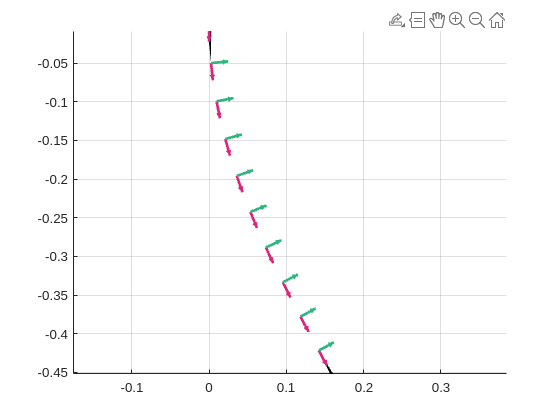

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on

Now let's apply a load to the tip of this rod and consider the reactions across it:

Q_tip = [0; -10; 0];
q = calc_external_wrench(segment_twists, Q_tip, g_0);
a_target = -q;

Now given the pressures of each muscle in the arm, compute the internal reaction force supplied along the length of the arm

p = [15; 0; 15; 0]; %kPa
reaction_forces = calc_reaction_wrench(segment_twists, p, struct_design);

% Now we plot the two against each other
figure("position", [0, 0, 1600, 400])
subplot(1, 3, 1)
hold on
plot(reaction_forces(1, 1), reaction_forces(3, 1), "ksquare", "markersize", 15, "linewidth", 3)
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o")
legend("s=0", "Reaction", location="Northwest")
xlabel("a_f")
ylabel("a_m")
grid on

subplot(1, 3, 2)
hold on
plot(q(1, 1), q(3, 1), "ksquare", "markersize", 15, "linewidth", 3);
plot(q(1, :), q(3, :), 'r-o');
xlabel("q_f")
ylabel("q_m")
legend("s=0")
grid on

subplot(1, 3, 3)
hold on
plot(reaction_forces(1, :), reaction_forces(3, :), "b-o");
plot(q(1, :), q(3, :), "r-o");
xlabel("Force")
ylabel("Moment")
legend("Reactions", "External requirements", location="southeast")
grid on

The crucial questions for extending our previous work to the variable curvature arm are:

- What will happen to this plot when we traverse the pressure contour? 

- How can we read "designability" from the variable curvature arm's pressure contour?

Now let's try doing this for a whole range of pressures along the pressure contour

N_edge = 25;
t = linspace(0, 4, 4*N_edge);
p_max_bellow = 50;
p_max_muscle = 100;
p_max = [p_max_bellow, p_max_muscle, p_max_muscle, p_max_bellow];
ps = outline_pressure_space(p_max, [1, 2, 1, 2], N_edge);
figure()
hold on
plot(t, ps(1, :), "b-", "linewidth", 2);
plot(t, ps(2, :), "r--", "linewidth", 2);
plot(t, ps(3, :), "b--", "linewidth", 2);
plot(t, ps(4, :), 'r-', "linewidth", 2);
set(gcf, "visible", true)
legend("Bellow", "Muscle", "Muscle", "Bellow")

mat_3d_rxns = zeros([size(reaction_forces), length(t)]);
for i = 1 : size(ps, 2)
    mat_3d_rxns(:, :, i) = calc_reaction_wrench(segment_twists, ps(:, i), struct_design);
end

% For each element within the segment, track how the reactions moved as we
% traversed the pressure contour.
paths_qf = zeros(N_poses, length(t));
paths_qm = zeros(N_poses, length(t));
text_labels = cell(1, N_poses);
for i = 1 : N_poses
    paths_qf(i, :) = squeeze(mat_3d_rxns(1, i, :));
    paths_qm(i, :) = squeeze(mat_3d_rxns(3, i, :));
    text_labels{i} = sprintf("s=%.2f", s(i));
end

mat_s = repmat(s, [N_edge*4, 1]);

figure()
hold on
plot3(a_target(1, :), a_target(3, :), s, 'r-o')
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, 'k');
plot3(paths_qf', paths_qm', mat_s, 'k');

xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements")
view(30, 20)
set(gcf, "visible", true)

% Find the pressure that will minimize the force residuals for when the arm
% is held at this shape.
tic
f_cost_pressure = @(pres) sum(vecnorm(check_equilibrium(segment_twists, Q_tip, pres, struct_design), 1));
[soln_p_min_residual] = fminunc(f_cost_pressure, [0; 0; 0; 0]);
soln_a_min_residual = calc_reaction_wrench(segment_twists, soln_p_min_residual, struct_design);
toc
% Find the pressure such that a(s=0) = [q_f, q_m]
tic
soln_p_rxn_at_base = fmincon(@(p) cost_first_reaction_diff(segment_twists, p, struct_design, a_target), [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]);
soln_a_rxn_at_base = calc_reaction_wrench(segment_twists, soln_p_rxn_at_base, struct_design);
toc

tic
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;
default_segment_twists(3, :) = 1e-5;

f_tip = @(p) cost_tip_pose_error(default_segment_twists, p, Q_tip, struct_design, poses(:, :, end));
soln_p_closest_tip = fmincon(f_tip, [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50]); % TODO: Rename to soln_p
toc
soln_a_closest_tip = calc_reaction_wrench(segment_twists, soln_p_closest_tip, struct_design);

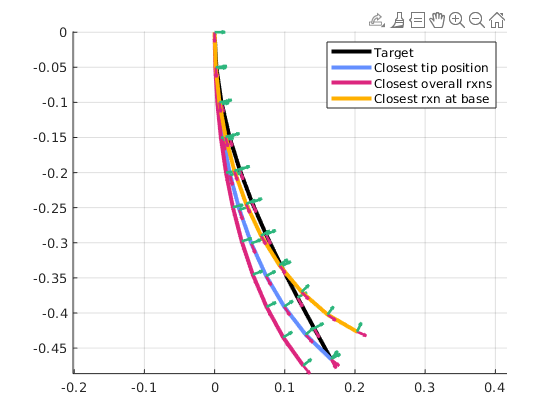

opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_min_residual, struct_design);
[soln_mimic_shape, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_rxn_at_base, struct_design);
[soln_mimic_rxns, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

f = @(mat_in) check_equilibrium(mat_in, Q_tip, soln_p_closest_tip, struct_design);
[soln_closest_tip, res, ~, output, J_end] = fsolve(f, default_segment_twists, opts);
if norm(res) > 0.01, disp(res), end

ax = axes(figure());
hold on

red = [220 38 126] / 255;
blue = [100 143 255] / 255;
yellow = [255 176 0] / 255;
green = [45 182 125] / 255;

plot_poses(calc_poses(g_0, segment_twists), ax, "k", true, 0.1)
plot_poses(calc_poses(g_0, soln_closest_tip), ax, struct(color=blue), true, 0.1);
plot_poses(calc_poses(g_0, soln_mimic_shape), ax, struct(color=red), true, 0.1);
plot_poses(calc_poses(g_0, soln_mimic_rxns), ax, struct(color=yellow), true, 0.1);

grid on
legend("Target", "Closest tip position", "Closest overall rxns", "Closest rxn at base")
set(gcf, "Visible", true)

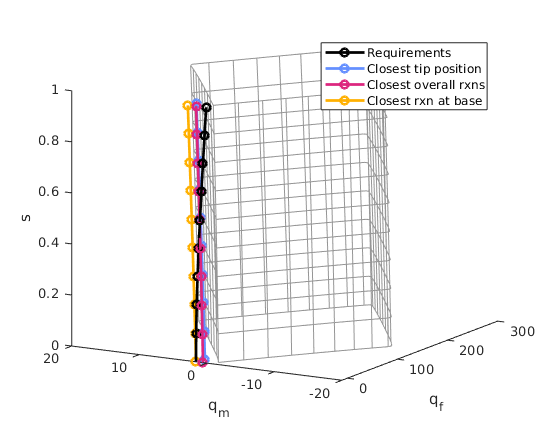

gray = [150 150 150] / 255;

figure()
hold on
plot3(a_target(1, :), a_target(3, :), s, 'k-o', "linewidth", 2)
plot3(soln_a_closest_tip(1, :), soln_a_closest_tip(3, :), s, '-o', "color", blue, "linewidth", 2)
plot3(soln_a_min_residual(1, :), soln_a_min_residual(3, :), s, '-o', "color", red, "linewidth", 2)
plot3(soln_a_rxn_at_base(1, :), soln_a_rxn_at_base(3, :), s, '-o', "color", yellow, "linewidth", 2)
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, "color", gray);
plot3(paths_qf', paths_qm', mat_s, "color", gray);

xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements", "Closest tip position", "Closest overall rxns", "Closest rxn at base")
view(-60, 15)
set(gcf, "visible", true)

## Full range of reachable reactions - evaluating actuation modes

**TODO!!! Move this into a separate notebook focused on the reaction outline**

Clearly our prism of reachable reactions is not the full space reachable reactions. However, what *is* the actual full space? 

With four actuators, the space of possible pressures is 4-dimensional hypercube. Our previous reaction moments only spanned a two-dimensional subspace within this space.

- The first way to do this is to extend the square boundary contour method for two actuators up to the boundary of the hypercube. However the hypercube has 32 edges so that's a lot of faces to consider

- The second, easier but less thorough way is through a monte-carlo method: randomly sample a lot of points in the 4D pressure space and see what reactions they produce.

% Clearly our prism is not the full reaction image. But what is the full
% reaction image?
% This begs the question: what is the actual full reaction image?
%
% We can do this in two ways: we can compute the reactions for pressures
% along the edges of the hypercube. OR, we can do a monte-carlo sampling of
% random points in the pressure space

% Sample a bunch of points in R4 bounded by [0; 0; 0; 0] and [50; 100; 100; 50]
rng(100);
p_max = [50, 100, 100, 50];
N_ps = 1000;
ps_monte = diag(p_max) * betarnd(0.2, 0.2, 4, N_ps); % By using a beta distribution we can bias towards the edges

figure("Position", [0, 0, 1200, 400])
subplot(1, 2, 1)
scatter(ps_monte(1, :), ps_monte(4, :));
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
scatter(ps_monte(2, :), ps_monte(3, :));
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

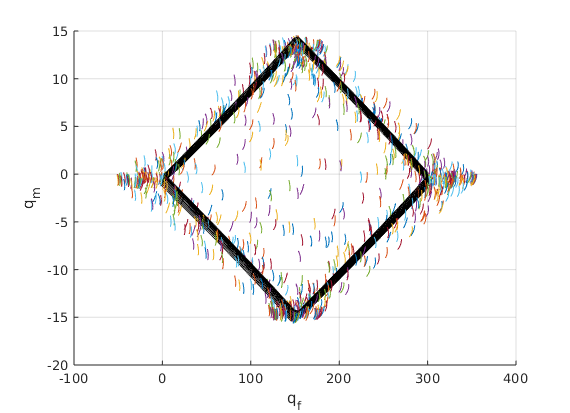

mat_rxns_3d_monte = zeros(3, N_poses, N_ps);
paths_qf_monte = zeros(N_poses, N_ps);
paths_qm_monte = zeros(N_poses, N_ps);

for i = 1 : N_ps
    % For each pressure, compute the corresponding reactions
    mat_rxns_3d_monte(:, :, i) = calc_reaction_wrench(segment_twists, ps_monte(:, i), struct_design);
end

for i = 1 : N_poses
    paths_qf_monte(i, :) = squeeze(mat_rxns_3d_monte(1, i, :));
    paths_qm_monte(i, :) = squeeze(mat_rxns_3d_monte(3, i, :));
end

figure()
hold on
mat_s_monte = repmat(s, [N_ps, 1]);
plot3(paths_qf_monte, paths_qm_monte, mat_s_monte);
plot3(paths_qf(:, 1:3:end)', paths_qm(:, 1:3:end)', s, 'k');
plot3(paths_qf', paths_qm', mat_s, 'k');
xlabel("q_f")
ylabel("q_m")
grid on
set(gcf, "Visible", true)

% Find the points that are on the outline of the base level, and then find
% their corresponding pressures. This will tell us which pressures to focus
% on.
bnd_qs = boundary(paths_qf_monte(1, :)', paths_qm_monte(1, :)', 0.1);
c = linspace(1, 10, length(bnd_qs));

figure("Position", [0, 0, 1500, 500])
subplot(1, 3, 1);
scatter(paths_qf_monte(1, bnd_qs), paths_qm_monte(1, bnd_qs), 75, c, "filled");
xlabel("q_f")
ylabel("q_m")

subplot(1, 3, 2)
scatter(ps_monte(1, bnd_qs), ps_monte(4, bnd_qs), 75, c, "filled");
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 3, 3)
scatter(ps_monte(2, bnd_qs), ps_monte(3, bnd_qs), 75, c, "filled");
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

## Reaction prism of a reachable shape

By this point I think we are reasonably convinced that this shape is not reachable, even though the algorithm to prove that took a minute to run (and that's just for a single segment!). To complete our understanding, let us now examine the reaction prism of a shape that we *can* reach. In this case, we will consider that of the previously found shape tip-pose closest to the previous target.

mat_rxns_closest_tip = zeros([size(reaction_forces), length(t)]);
for i = 1 : size(ps_monte, 2)
    mat_rxns_closest_tip(:, :, i) = calc_reaction_wrench(soln_closest_tip, ps_monte(:, i), struct_design);
end

% For each element within the segment, track how the reactions moved as we
% traversed the pressure contour.
paths_qf_closest_tip = zeros(N_poses, length(t));
paths_qm_closest_tip = zeros(N_poses, length(t));
text_labels = cell(1, N_poses);
for i = 1 : N_poses
    paths_qf_closest_tip(i, :) = squeeze(mat_rxns_closest_tip(1, i, :));
    paths_qm_closest_tip(i, :) = squeeze(mat_rxns_closest_tip(3, i, :));
    text_labels{i} = sprintf("s=%.2f", s(i));
end

rxns_closest_tip = calc_reaction_wrench(soln_closest_tip, soln_p_closest_tip, struct_design);
q_closest_tip = -calc_external_wrench(soln_closest_tip, Q_tip, struct_design.g_0);

figure("Position", [0, 0, 1200, 400])
subplot(1, 2, 1)
hold on
plot3(q_closest_tip(1, :), q_closest_tip(3, :), s, 'k-o', "linewidth", 2)
plot3(rxns_closest_tip(1, :), rxns_closest_tip(3, :), s, '-o', "color", blue, "linewidth", 2)
plot3(paths_qf_closest_tip(:, 1:3:end)', paths_qm_closest_tip(:, 1:3:end)', s, "color", gray);
plot3(paths_qf_closest_tip', paths_qm_closest_tip', mat_s, "color", gray);
xlabel("q_f")
ylabel("q_m")
zlabel("s")
legend("Requirements", "Closest possible")
view(-60, 15)
set(gcf, "visible", true)

ax = subplot(1, 2, 2)
hold on

plot_poses(calc_poses(g_0, segment_twists), ax, "k", true, 0.1)
plot_poses(calc_poses(g_0, soln_closest_tip), ax, struct(color=blue), true, 0.1);

grid on
legend("Arm 1", "Arm 2")
set(gcf, "Visible", true)

## Valid design space

The purpose of the reaction contour is to efficiently sample the valid design space. Let us first naively sample the reaction space without it.

We have two options available:

- The most "accurate" way is to check for each arm design what the closest it can reach to the tip pose is. There is a question here of whether "closeness" is of tip position vs pose (do you consider angle?)

- A quicker way is to check the reaction residual

% WARNING: The following code takes 6 hours to run!!!
% DON'T FORGET TO SAVE YOUR DATA
run = false; 
if ~run
    error("Not running the code")
end

Not running the code


% Create a uniform sampling of the design space
rho_min = 0.02;
rho_max = 0.15;
l_0_min = 0.5;
l_0_max = 0.6;
N_designs_per_dim = 20;
%
rhos = linspace(rho_min, rho_max, N_designs_per_dim);
l_0s = linspace(l_0_min, l_0_max, N_designs_per_dim);
[R, L] = meshgrid(rhos, l_0s);
designs_rl = [R(:)'; L(:)'];
N_designs = size(designs_rl, 2);

% Preallocate storage space for loop times
times = zeros(1, N_designs);
p_solns = zeros(4, N_designs);
pose_residuals = zeros(1, N_designs);
reaction_residuals = zeros(1, N_designs);

% Initialize optimization initial values outside of the loop
default_segment_twists = zeros(size(segment_twists));
default_segment_twists(1, :) = l_0;
default_segment_twists(3, :) = 1e-5;

tic
for i = 1 : N_designs
    t_start = tic;
    design_i = designs_rl(:, i);
    struct_design_i = make_antagonistic_struct_design(struct_design, design_i);

    opts = optimoptions("fmincon", Display="off");
    
    f_tip = @(p) cost_tip_pose_error(default_segment_twists, p, Q_tip, struct_design_i, poses(:, :, end));
    [p_solns(:, i), pose_residuals(i)] = fmincon(f_tip, [0; 0; 0; 0], [], [], [], [], [0; 0; 0; 0], [50; 100; 100; 50], [], opts); % TODO: Rename to soln_p
    reaction_residuals(i) = sum(vecnorm(check_equilibrium(segment_twists, Q_tip, p_solns(:, i), struct_design_i), 1));
    
    times(i) = toc(t_start);
end

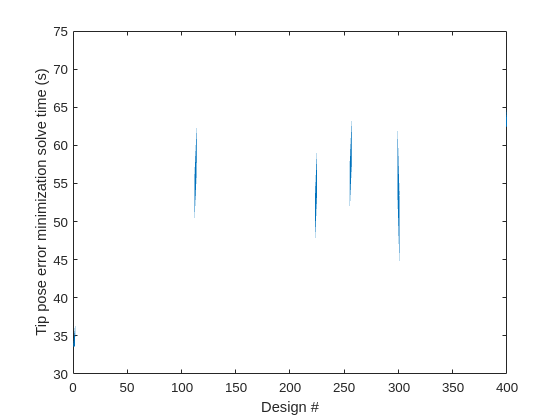

figure()
plot(times, "linewidth", 1.5);
xlabel("Design #")
ylabel("Tip pose error minimization solve time (s)")

% I forgot to store the distance-to-target costs
tic
pose_residuals = zeros(1, N_designs);
for i = 1 : N_designs
    p_i = p_solns(:, i);

    design_i = designs_rl(:, i);
    struct_design_i = struct_design;
    struct_design_i.rhos  = [design_i(1), 0.02, 0.02, design_i(1)]; % Here we just sweep the outer radius
    struct_design_i.l_0 = design_i(2);
    
    pose_residuals(i) = cost_tip_pose_error(default_segment_twists, p_i, Q_tip, struct_design_i, poses(:, :, end));
end
toc

Elapsed time is 44.463096 seconds.


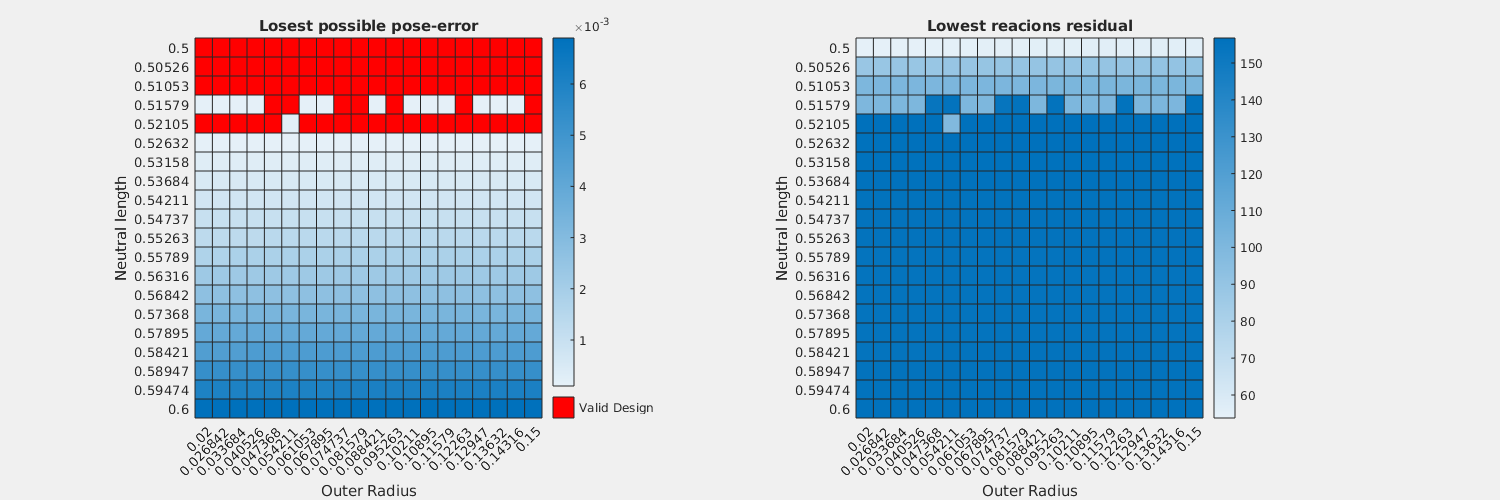

% Reshape the vectors back into meshgrid form
mat_pose_residuals = reshape(pose_residuals, size(R));
mat_reaction_residuals = reshape(reaction_residual, size(R));

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
hmap_data = round(mat_pose_residuals, 4);
hmap_data(hmap_data == 0) = nan;
hmap = heatmap(R(1, :), L(:, 1), hmap_data);
hmap.MissingDataColor = [1 0 0];
hmap.MissingDataLabel = 'Valid Design';
xlabel("Outer Radius")
ylabel("Neutral length")
title("Losest possible pose-error")

subplot(1, 2, 2);
heatmap(R(1, :), L(:, 1), mat_reaction_residuals);
xlabel("Outer Radius")
ylabel("Neutral length")
title("Lowest reacions residual")
set(gcf, "Visible", true);

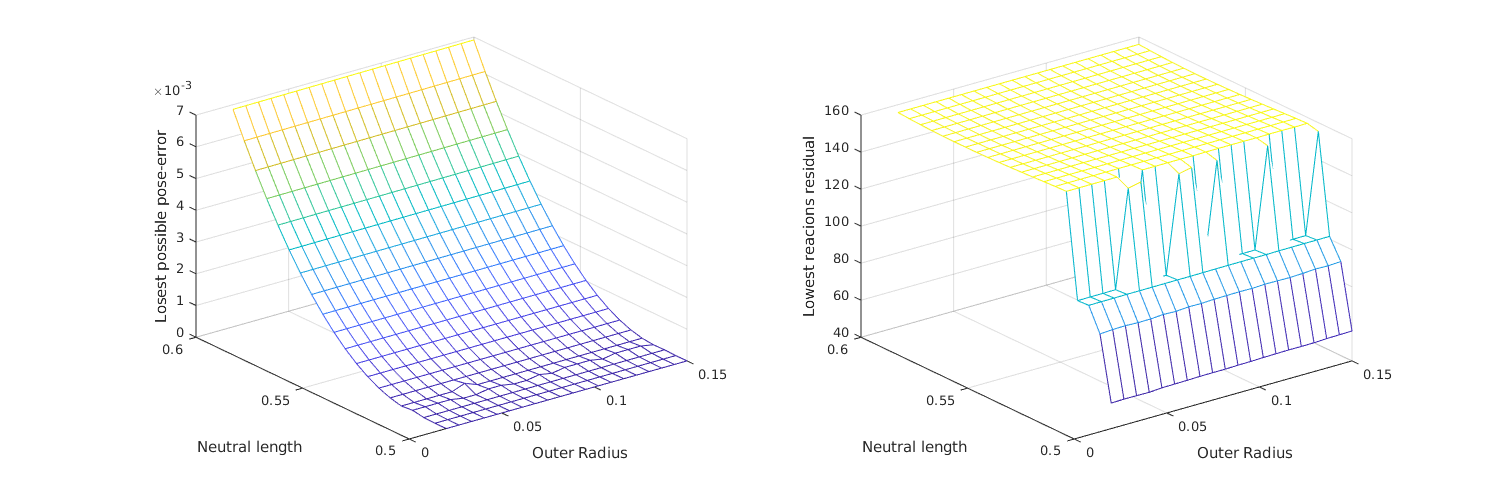

figure("Position", [0, 0, 1500, 500])
subplot(1, 2, 1);
mesh(R, L, mat_pose_residuals);
xlabel("Outer Radius")
ylabel("Neutral length")
zlabel("Losest possible pose-error")

subplot(1, 2, 2);
mesh(R, L, mat_reaction_residuals);
xlabel("Outer Radius")
ylabel("Neutral length")
zlabel("Lowest reacions residual")
set(gcf, "Visible", true);

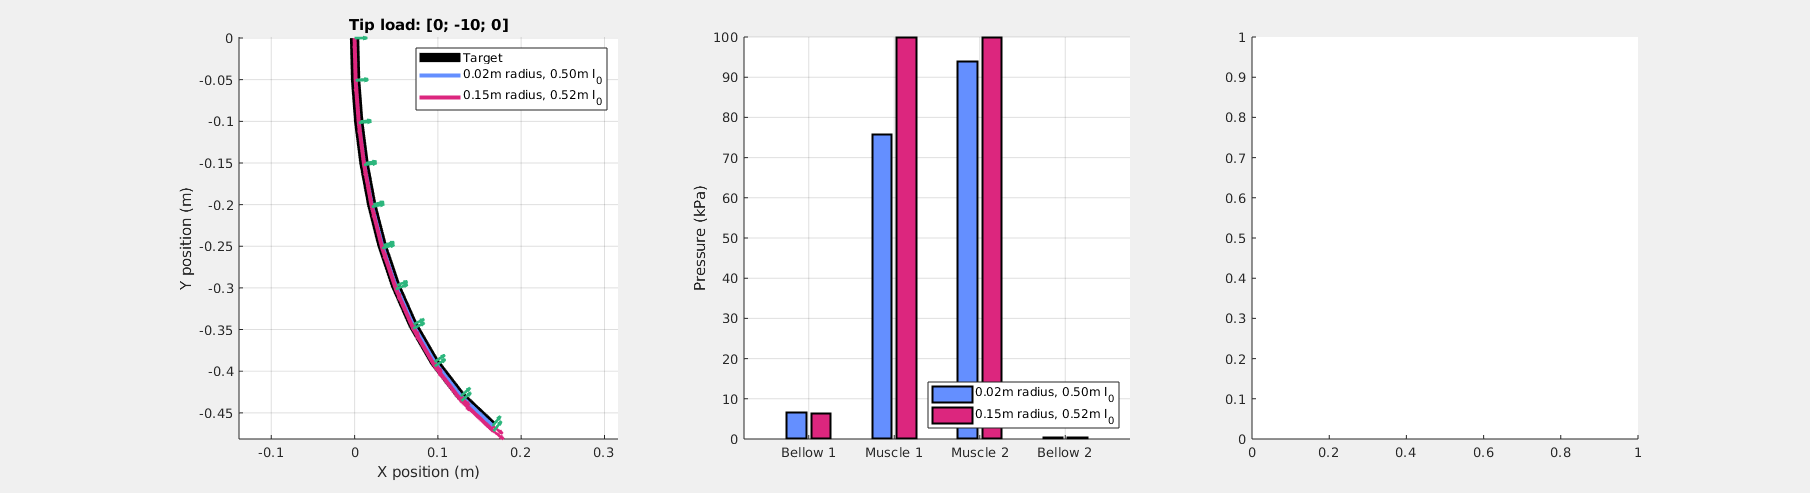

% Plot the equilibrium-shapes from two parts of the valid design space:
cell_mat_p_solns = reshape(num2cell(p_solns', 2), [N_designs_per_dim, N_designs_per_dim]);
cell_mat_designs = reshape(num2cell(designs_rl', 2), [N_designs_per_dim, N_designs_per_dim]);

% Pick out the two designs, which will be the first and last elements of
% the valid design space
i_valid_designs = find(mat_pose_residuals < 1e-4);

i_designs_to_plot = [i_valid_designs(1), i_valid_designs(end)];

segment_twists = zeros(3, N_poses, length(i_designs_to_plot));
names = strings(1, length(i_designs_to_plot));

% Iterate through the list of indices of designs that we want to visualize
for i = 1 : length(i_designs_to_plot)
    % Get the design parameters and pressure 
    i_design = i_designs_to_plot(i);
    design_i_rl = designs_rl(:, i_design);
    struct_design_i = make_antagonistic_struct_design(struct_design, design_i_rl);

    names(i) = sprintf("%.2fm radius, %.2fm l_0", design_i_rl(1), design_i_rl(2));

    p_soln_i = p_solns(:, i_design);
    
    % Solve the statics problem for this design with the pressures that
    % supposedly will get it to the target
    opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
    f = @(mat_in) check_equilibrium(mat_in, Q_tip, p_soln_i, struct_design_i);
    [segment_twists(:, :, i), residual_i] = fsolve(f, default_segment_twists, opts);
end

%% Plot all of the results
figure("Position", [0, 0, 1800, 500], "Visible", true)
ax = subplot(1, 3, 1);
hold on
colors = [blue; red; yellow];

% Plot the target shape
plot_poses(calc_poses(g_0, segment_twists), ax, struct(color="k", linewidth=7), true, 0.1)
for i = 1 : length(i_designs_to_plot)
    % For each segment twist, compute the corresponding poses and plot them
    plot_poses(calc_poses(g_0, segment_twists(:, :, i)), ax, struct(color=colors(i, :), linewidth=3), true, 0.1);
end
legend(["Target", names])
grid on
xlabel("X position (m)")
ylabel("Y position (m)")
title("Tip load: [0; -10; 0]");
ax = subplot(1, 3, 2);
hold on;
bar_xlabels = ["Bellow 1", "Muscle 1", "Muscle 2", "Bellow 2"];
bar_handles = bar(bar_xlabels, p_solns(:, i_designs_to_plot), "Linewidth", 1.5);
for i = 1 : length(bar_handles)
    bar_handles(i).FaceColor = 'flat';
    bar_handles(i).CData = colors(i, :);
end
legend(names, "location", "southeast")
ylabel("Pressure (kPa)")
grid on

ax = subplot(1, 3, 3);

rounded_residuals = round(mat_pose_residuals, 4);
rounded_residuals(rounded_residuals == 0) = nan;

function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function ps = outline_pressure_space(max_ps, actuation_mode, N_edge)
    %%% Create a square path in pressure-space with N_edge points along each
    %%% edge using a corner definition: min_ps defines the bottom left
    %%% corner, and max_ps defines the top right corner. The path begins
    %%% and ends at the bottom left corner.
    %%%
    %%% Parameters:
    %%%  - max_ps: [60, 100, 100, 60] (kpa)
    %%%  - actuation_mode: [1 2 1 2]
    %%%  - N_edge: 50

    % Determine the phases of each trapezoid wave based on the actuation
    % modes. 
    % Currently mode-2 is defined starting a quarter period later than mode1
    phases = zeros(size(actuation_mode));
    for i = 1 : length(actuation_mode)
        mode_i = actuation_mode(i);
        
        if mode_i == 1
            phases(i) = 0;
        elseif mode_i == 2
            phases(i) = 1;
        end
    end
    
    t = linspace(0, 4, N_edge*4);
    ps = zeros(length(max_ps), length(t));
    for i = 1 : length(max_ps)
        ps(i, :) = max_ps(i) * trapezoid_wave(t - phases(i));
    end
end

function sig = trapezoid_wave(s)
    %%% Sample a trapzoid wave with period 1s at times s.
    %%% The trapezoid has amplitude 0.5 and is centered at 0.5
    %%% ie, it switches between 0 and 1.
    s = mod(s, 4);
    sig = zeros(size(s));
    for i = 1 : length(s)
        s_i = s(i);
        
        if s_i < 1
            sig(i) = 1 * (s_i);
        elseif (s_i >= 1) && (s_i < 2)
            sig(i) = 1;
        elseif (s_i >= 2) && (s_i < 3)
            sig(i) = -1 * (s_i - 2) + 1;
        else
            sig(i) = 0;
        end
    end
end

function cost = cost_first_reaction_diff(twists, pressure, struct_design, a_target)
    rxns = calc_reaction_wrench(twists, pressure, struct_design);
    cost = norm(rxns(:, 1) - a_target(:, 1));
end

function cost = cost_tip_pose_error(twists_0, pressure, Q_tip, struct_design, g_target)
    opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
    f = @(mat_in) check_equilibrium(mat_in, Q_tip, pressure, struct_design);
    
    soln = fsolve(f, twists_0, opts);
    
    poses = calc_poses(struct_design.g_0, soln);
    delta_g_extrinsic = Pose2.vee(poses(:, :, end)) - Pose2.vee(g_target);
    K = diag([1 1 0]);
    cost = delta_g_extrinsic' * K * delta_g_extrinsic;
    %delta_g = inv(poses(:, :, end)) * g_target;
    %cost = norm(Twist2.vee(logm(delta_g)));
end

function struct_design_out = make_antagonistic_struct_design(struct_design_base, design_rl)
    struct_design_out = struct_design_base;
    struct_design_out.rhos  = [design_rl(1), 0.02, 0.02, design_rl(1)]; % Here we just sweep the outer radius
    struct_design_out.l_0 = design_rl(2);
end